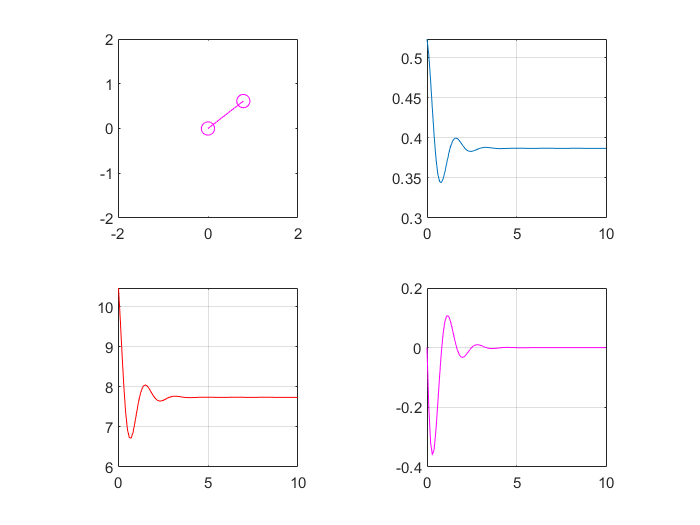

clear
close
clc

dt=0.1;
ts=10;
t=0:dt:ts;

m=1;
l=1;
g=-9.8;

thdot(length(t))=0;
thdotdot=0;
th=pi/3;
Tau=0;
Kp=20;
Kd=2;
th_d=pi/6;             %desired angle
thdot_d=0;          %desired angular velocity

for i=1:length(t)
    e(i)=th(i)-th_d;
    Tau(i)=Kp*(th(i)-th_d)+Kd*(thdot(i)-thdot_d);
    thdotdot=(-Tau(i)-m*g*l*sin(th(i)))/(m*l^2)-0.5*thdot(i);
    thdot(i+1)=thdot(i)+thdotdot*dt;
    th(i+1)=th(i)+thdot(i+1)*dt;
    
    subplot(2,2,1)
    plot([0 l*sin(th(i))],[0 l*cos(th(i))],'m-o','MarkerSize',8);
    axis([-2 2 -2 2]);
    axis square;
    
    subplot(2,2,2)
    plot(t(1:i),e)
%     axis([0 1 0 10]);
    axis square;
    grid on;
    
    subplot(2,2,3)
    plot(t(1:i),Tau,'r')
%     axis([0 12 0 10]);
    axis square;
    grid on;
    
    subplot(2,2,4)
    plot(t(1:i),thdot(1:i),'m')
%     axis([-1 1 0 10]);
    axis square;
    grid on;
    pause(dt);
end

% figure
% plot(t,e)
